clear all;
close all;
clc;

% calculate and plot state value

Animal = {'tph209','tph210','tph218','tph227','tph228'}; %'s19';
Date = {'20230819','20230819','20230819','20230819','20230819'};
totalTrial = 150;
Key = {'heavy90h','heavy90h','heavy90h','heavy90h','heavy90h'};
gamma = 0.9; % discount factor
position_range = [657 672]; % [630-647]
fps = 10;
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022'; % Linux
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
% data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation'  filesep Date '_' Animal '_' Key]; % Linux
% load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
% data = behavior_sequence_fps;
output_dir = '/home/naohiro/Desktop/Doya_rotation/analysis/output/behavior/231111/'; %_fps

data_folders = cell(1,length(Animal));
% data_folders = [];
data = cell(length(Animal),totalTrial);
for i = 1:length(Animal)
    data_folders(i) = {['/media/naohiro/ADATA HV620S/Doya_rotation/202308' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat']);
    data(i,:) = behavior_sequence_fps; %behavior_sequence; %
end

% load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat'])

% bin the state and action to calculate state value and action value
behavior_sequence_discretized = cell(size(data));
for j_animal = 1:length(Animal) 
    for i_trial = 1:totalTrial
        % bin lever position (657-672 -> 5-1) %(630-647 -> 6-1)
        position_temp = data{j_animal,i_trial}(:,3);
        position_discrete = 6 - min(max(floor((position_temp - (position_range(1)-6))/4),1),5);
    %     position_discrete = 7 - min(max(floor((position_temp - 623)/4),1),6);
    %     position_discrete = zeros(length(position_temp));
    %     for j_time = 1:length(position_temp)
    %         if position_temp(j_time) <= 
        % bin applied force (0-0.7 -> 0-7)
        force_temp = data{j_animal,i_trial}(:,4);
        force_discrete = min(max(floor(force_temp/0.1),0),7);
    %     force_discrete = min(max(idivide(force_temp,0.1,'floor'),0),7);
        behavior_sequence_discretized{j_animal,i_trial} = cat(2,cat(2,data{j_animal,i_trial},position_discrete),force_discrete);
    end
end

% analyze first 50 of last 50 trials as before and after adaptation
behavior_adapt = cell(length(Animal),2,50);
for j_animal = 1:length(Animal)
    behavior_adapt(j_animal,1,:) = behavior_sequence_discretized(j_animal,1:50); % behavior_before_adapt
    behavior_adapt(j_animal,2,:) = behavior_sequence_discretized(j_animal,length(data)-49:length(data)); % behavior_after_adapt
end

% calculate state value for each discretized state
% 2 (resistance) * 5 (position) = 10 states % 2 (resistance) * 6 (position) = 12 states
state_value = cell(length(Animal),2,10);
for j_animal = 1:length(Animal)
    for k = 1:2
        for i_trial = 1:50
            % resistance for each trial
            if behavior_adapt{j_animal,k,i_trial}(1,2) == 8
                resistance_trial = 1;
            else 
                resistance_trial = 2;
            end
            % rewarded step (end of trial) or not (0)
            if max(behavior_adapt{j_animal,k,i_trial}(:,5)) == 1
                rewarded_trial = length(behavior_adapt{j_animal,k,i_trial});
            else 
                rewarded_trial = 0;
            end
            % add state_value of each step
            for j_step = 1:size(behavior_adapt{j_animal,k,i_trial},1)
                state_temp = (resistance_trial-1)*5+behavior_adapt{j_animal,k,i_trial}(j_step,7);
                if rewarded_trial >= 1
                    state_value_temp = gamma.^(rewarded_trial-j_step);
                else
                    state_value_temp = 0;
                end
                state_value{j_animal,k,state_temp} = [state_value{j_animal,k,state_temp} state_value_temp];
            end
        end
    end
end

temp_state_value_average = zeros(length(Animal),2,10);
for j_animal = 1:length(Animal)
    for i = 1:10
        temp_state_value_average(j_animal,1,i) = mean(state_value{j_animal,1,i});
        temp_state_value_average(j_animal,2,i) = mean(state_value{j_animal,2,i});
    end
end
state_value_average = squeeze(nanmean(temp_state_value_average,1));
% rewarded after how many steps or not

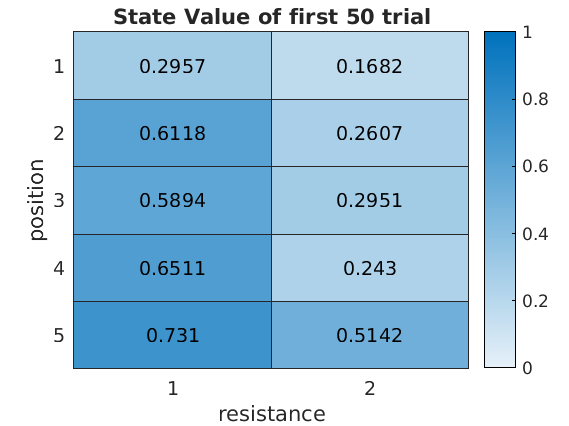

% plot state value
state_value_average_reshape = reshape(state_value_average(1,:),[5,2]);
heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of first 50 trial','XLabel','resistance','YLabel','position')
filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_State_Value_first50.png'];
saveas(gcf,filename);

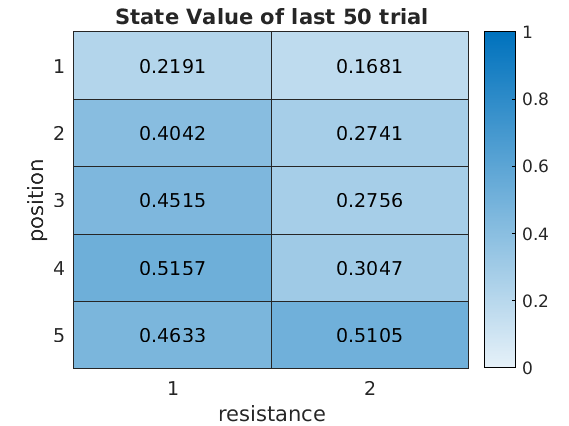

state_value_average_reshape = reshape(state_value_average(2,:),[5,2]);
heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of last 50 trial','XLabel','resistance','YLabel','position')
filename = [output_dir strrep(strjoin(Date),' ','_') '_' strrep(strjoin(Animal),' ','_') '_State_Value_last50.png'];
saveas(gcf,filename);

% analyze by binned 20 trials
num_bins = 6; % 6 % number of bins
num_width = 25; % 20
behavior_adapt = cell(length(Animal),num_bins,num_width);
for j_animal = 1:length(Animal)
    for i = 1:num_bins
    %     if i == 6
    %         behavior_adapt(6,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-19:length(behavior_sequence_processed));
    %     else
            behavior_adapt(j_animal,i,:) = behavior_sequence_discretized(j_animal,(i-1)*num_width+1:i*num_width);
    %     end
    end
end
% behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% behavior_adapt(2,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-49:length(behavior_sequence_processed)); % behavior_after_adapt

% calculate state value for each discretized state
% 2 (resistance) * 5 (position) = 10 states % 2 (resistance) * 6 (position) = 12 states
state_value = cell(length(Animal),num_bins,10);
for j_animal = 1:length(Animal)
    for k = 1:num_bins
        for i_trial = 1:num_width
            % resistance for each trial
            if behavior_adapt{j_animal,k,i_trial}(1,2) == 8
                resistance_trial = 1;
            else 
                resistance_trial = 2;
            end
            % rewarded step (end of trial) or not (0)
            if max(behavior_adapt{j_animal,k,i_trial}(:,5)) == 1
                rewarded_trial = length(behavior_adapt{j_animal,k,i_trial});
            else 
                rewarded_trial = 0;
            end
            % add state_value of each step
            for j_step = 1:size(behavior_adapt{j_animal,k,i_trial},1)
                state_temp = (resistance_trial-1)*5+behavior_adapt{j_animal,k,i_trial}(j_step,7);
                if rewarded_trial >= 1
                    state_value_temp = gamma.^(rewarded_trial-j_step);
                else
                    state_value_temp = 0;
                end
                state_value{j_animal,k,state_temp} = [state_value{j_animal,k,state_temp} state_value_temp];
            end
        end
    end
end

temp_state_value_average = zeros(length(Animal),num_bins,10);
for j_animal = 1:length(Animal)
    for k = 1:num_bins
        for i = 1:10
            temp_state_value_average(j_animal,k,i) = mean(state_value{j_animal,k,i});
        end
    end
end
state_value_average = squeeze(nanmean(temp_state_value_average,1));

% rewarded after how many steps or not

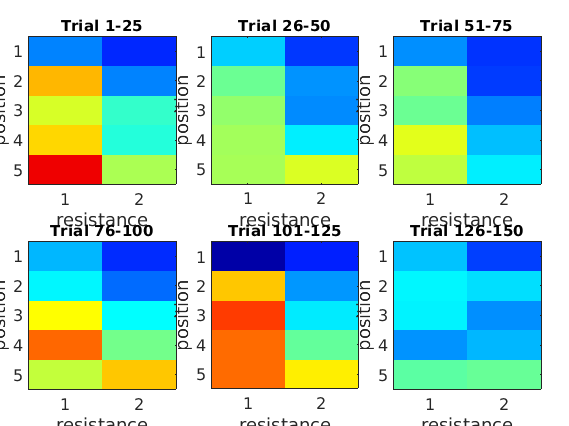

% plot state value
% addpath(['C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\PCA_and_ICA\Subaxis']);
addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
for i = 1:num_bins
% state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% heatmap(state_value_average_reshape)
    subaxis(2,3,i, 'Spacing', 0.02, 'Padding', 0.02, 'Margin', 0.03);
%     clims = [-3 10]; % use clims specified by the previous cell
%     image = mean(mean_RecICA_Temp(:,time_points(i,1)*fps/1000:time_points(i,2)*fps/1000),2);
    state_value_average_reshape = reshape(state_value_average(i,:),[5,2]); %mean(mean_RecICA_lift(:,timepoints(i,1):timepoints(i,2)),2);
    imagesc(state_value_average_reshape,[0 1]);
    colormap jet;
    axis square;
%     axis off;
    title(['Trial ' num2str(1+(i-1)*num_width) '-' num2str(i*num_width)], 'FontSize',8);
    xlabel('resistance');
    ylabel('position');
end
filename = [output_dir strrep(strjoin(Date),' ','_')  '_' strrep(strjoin(Animal),' ','_')  '_State_Value_25bin.png'];
saveas(gcf,filename);

% analyze by binned 20 trials
num_bins = 12; % 12; % 6 % number of bins
num_width = 12; % 20
behavior_adapt = cell(length(Animal),num_bins,num_width);

for j_animal = 1:length(Animal)
    for i = 1:num_bins
    %     if i == 6
    %         behavior_adapt(6,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-19:length(behavior_sequence_processed));
    %     else
        if rem(i,2)==0
            behavior_adapt(j_animal,i,:) = behavior_sequence_discretized(j_animal,(i/2)*25-num_width+1:(i/2)*25);
        else 
            behavior_adapt(j_animal,i,:) = behavior_sequence_discretized(j_animal,((i-1)/2)*25+1:((i-1)/2)*25+num_width);        
        end
    end
end
% behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% behavior_adapt(2,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-49:length(behavior_sequence_processed)); % behavior_after_adapt

% calculate state value for each discretized state
% 2 (resistance) * 5 (position) = 10 states % 2 (resistance) * 6 (position) = 12 states
state_value = cell(length(Animal),num_bins,10);
for j_animal = 1:length(Animal)
    for k = 1:num_bins
        for i_trial = 1:num_width
            % resistance for each trial
            if behavior_adapt{j_animal,k,i_trial}(1,2) == 8
                resistance_trial = 1;
            else 
                resistance_trial = 2;
            end
            % rewarded step (end of trial) or not (0)
            if max(behavior_adapt{j_animal,k,i_trial}(:,5)) == 1
                rewarded_trial = length(behavior_adapt{j_animal,k,i_trial});
            else 
                rewarded_trial = 0;
            end
            % add state_value of each step
            for j_step = 1:size(behavior_adapt{j_animal,k,i_trial},1)
                state_temp = (resistance_trial-1)*5+behavior_adapt{j_animal,k,i_trial}(j_step,7);
                if rewarded_trial >= 1
                    state_value_temp = gamma.^(rewarded_trial-j_step);
                else
                    state_value_temp = 0;
                end
                state_value{j_animal,k,state_temp} = [state_value{j_animal,k,state_temp} state_value_temp];
            end
        end
    end
end

temp_state_value_average = zeros(length(Animal),num_bins,10);
for j_animal = 1:length(Animal)
    for k = 1:num_bins
        for i = 1:10
            temp_state_value_average(j_animal,k,i) = mean(state_value{j_animal,k,i});
        end
    end
end
state_value_average = squeeze(nanmean(temp_state_value_average,1));

% rewarded after how many steps or not

% plot state value
addpath(['C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\PCA_and_ICA\Subaxis']);

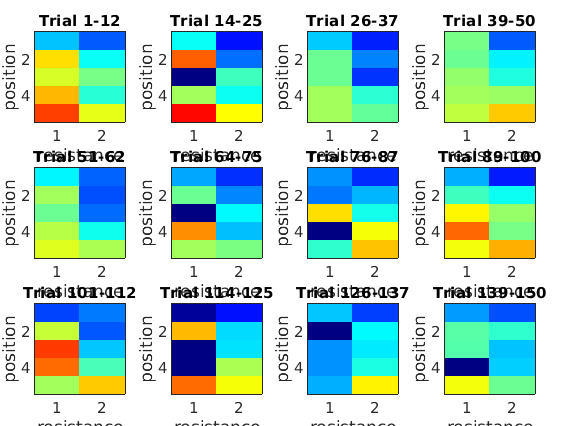

for i = 1:num_bins
% state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% heatmap(state_value_average_reshape)
    subaxis(3,4,i, 'Spacing', 0.02, 'Padding', 0.03, 'Margin', 0.03);
%     clims = [-3 10]; % use clims specified by the previous cell
%     image = mean(mean_RecICA_Temp(:,time_points(i,1)*fps/1000:time_points(i,2)*fps/1000),2);
    state_value_average_reshape = reshape(state_value_average(i,:),[5,2]); %mean(mean_RecICA_lift(:,timepoints(i,1):timepoints(i,2)),2);
    imagesc(state_value_average_reshape,[0 1]);
    colormap jet;
    axis square;
%     axis off;
    if rem(i,2)==0
        title(['Trial ' num2str((i/2)*25-num_width+1) '-' num2str((i/2)*25)], 'FontSize',8);
    else 
%         behavior_adapt(i,:) = behavior_sequence_discretized(((i-1)/2)*25+1:((i-1)/2)*25+num_width); 
        title(['Trial ' num2str(((i-1)/2)*25+1) '-' num2str(((i-1)/2)*25+num_width)], 'FontSize',8);
    end
%     title(['Trial ' num2str(1+(i-1)*num_width) '-' num2str(i*num_width)], 'FontSize',8);
    xlabel('resistance');
    ylabel('position');
end
filename = [output_dir strrep(strjoin(Date),' ','_')  '_' strrep(strjoin(Animal),' ','_')  '_State_Value_12bin.png'];
saveas(gcf,filename);

% analyze by linearly increase the contribution of past trials
effective_trials = 50; % maximam trial which affect current state or action value
% calculate state value for each discretized state
% 2 (resistance) * 5 (position) = 10 states % 2 (resistance) * 6 (position) = 12 states
trial_num = length(data);
state_value = cell(length(Animal),trial_num,10);
for j_animal = 1:length(Animal)
    for i_trial = 1:trial_num
         % resistance for each trial
        if behavior_sequence_discretized{j_animal,i_trial}(1,2) == 8
            resistance_trial = 1;
        else 
            resistance_trial = 2;
        end
        % rewarded step (end of trial) or not (0)
        if max(behavior_sequence_discretized{j_animal,i_trial}(:,5)) == 1
            rewarded_trial = size(behavior_sequence_discretized{j_animal,i_trial},1);
        else 
            rewarded_trial = 0;
        end
        % calculate state_value of each step
        for j_step = 1:size(behavior_sequence_discretized{j_animal,i_trial},1)
            state_temp = (resistance_trial-1)*5+behavior_sequence_discretized{j_animal,i_trial}(j_step,7);
            if rewarded_trial >= 1
                state_value_temp = gamma.^(rewarded_trial-j_step);
            else
                state_value_temp = 0;
            end
            state_value{j_animal,i_trial,state_temp} = [state_value{j_animal,i_trial,state_temp} state_value_temp];
        end   
    end
end

temp_state_value_average = zeros(length(Animal),trial_num,10);
for j_animal = 1:length(Animal)
    for i_trial = 1:trial_num
        for i = 1:10
            temp_state_value_average(j_animal,i_trial,i) = mean(state_value{j_animal,i_trial,i});
        end
    end
end
state_value_average = squeeze(nanmean(temp_state_value_average,1));

% save state value sequence
state_value_weighted_averages = zeros(length(Animal),trial_num,10);
for j_animal = 1:length(Animal)
    for i_trial = 1:trial_num
        for i = 1:10
            if i_trial > (effective_trials-1)
                nan_idx = ~isnan(temp_state_value_average(j_animal,i_trial-(effective_trials-1):i_trial,i));
                if sum(nan_idx) == 0
                    continue;
                else
                    state_value_weighted_averages(j_animal,i_trial,i) = squeeze(nansum(temp_state_value_average(j_animal,i_trial-(effective_trials-1):i_trial,i).*(1:effective_trials))/sum(nan_idx.*(1:effective_trials)));
                end
            else
                nan_idx = ~isnan(temp_state_value_average(j_animal,1:i_trial,i));
                if sum(nan_idx) == 0
                    continue;
                else               
                    state_value_weighted_averages(j_animal,i_trial,i) = squeeze(nansum(temp_state_value_average(j_animal,1:i_trial,i).*(1:i_trial))/sum(nan_idx.*(1:i_trial)));
                end
            end
        end
    end
    StateValue = squeeze(state_value_weighted_averages(j_animal,:,:));
    save([strjoin(data_folders(j_animal)) filesep strjoin(Animal(j_animal)) '_behavior_' strjoin(Date(j_animal)) '_' strjoin(Key(j_animal)) '.mat'], 'StateValue', '-append');
%     filename = [output_dir Date{j_animal} '_' Animal{j_animal} '_state_value.csv'];
%     writematrix(squeeze(state_value_weighted_averages(j_animal,:,:)),filename);
end

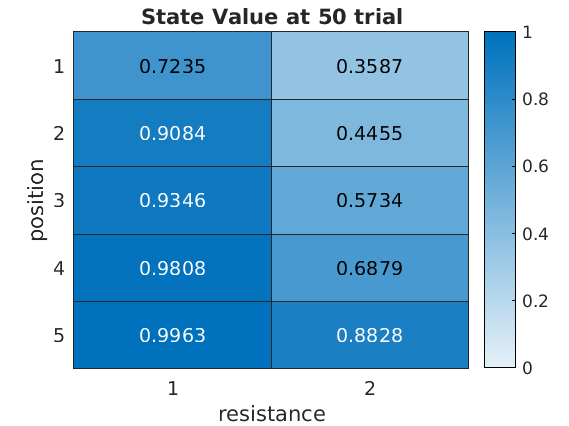

% plot state value at trial50 
clf('reset')
state_value_weighted_average = zeros(1,10);
% for i_trial = 1:effective_trials
%     for i = 1:12
%         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%     end
% end
for i = 1:10
    sum_weights = 0;
    for i_trial = 1:effective_trials
        if ~isnan(state_value_average(50-effective_trials+i_trial,i))
            state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
            sum_weights = sum_weights + i_trial;
        end
    end
    state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

state_value_weighted_average_reshape = reshape(state_value_weighted_average,[5,2]);
heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 50 trial','XLabel','resistance','YLabel','position')
filename = [output_dir strrep(strjoin(Date),' ','_')  '_' strrep(strjoin(Animal),' ','_')  '_State_Value_at50.png'];
saveas(gcf,filename);

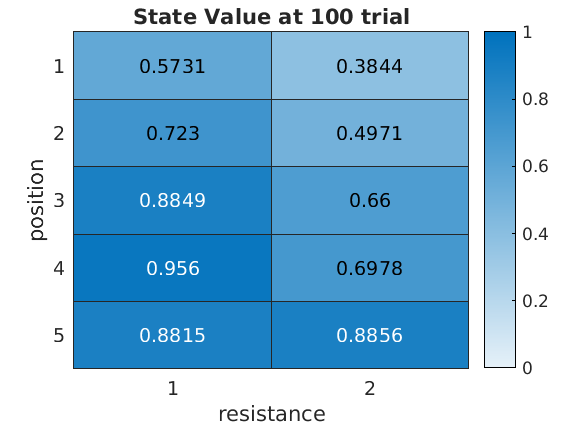

% plot state value at trial100 
% clf('reset')
state_value_weighted_average = zeros(1,10);
% for i_trial = 1:effective_trials
%     for i = 1:12
%         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%     end
% end
for i = 1:10
    sum_weights = 0;
    for i_trial = 1:effective_trials
        if ~isnan(state_value_average(100-effective_trials+i_trial,i))
            state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(100-effective_trials+i_trial,i);
            sum_weights = sum_weights + i_trial;
        end
    end
    state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

state_value_weighted_average_reshape = reshape(state_value_weighted_average,[5,2]);
heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 100 trial','XLabel','resistance','YLabel','position')
filename = [output_dir strrep(strjoin(Date),' ','_')  '_' strrep(strjoin(Animal),' ','_') '_State_Value_at100.png'];
saveas(gcf,filename);

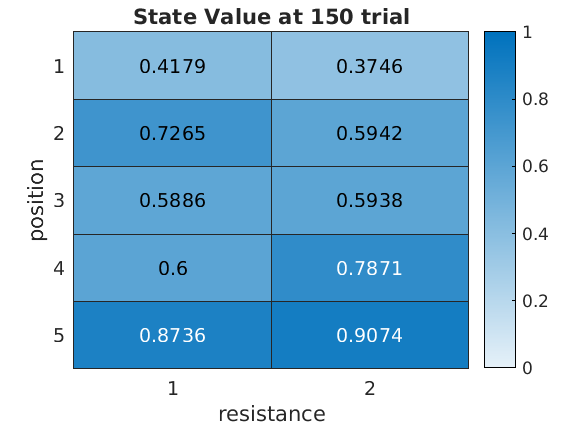

% plot state value at trial150 
% clf('reset')
state_value_weighted_average = zeros(1,10);
% for i_trial = 1:effective_trials
%     for i = 1:12
%         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%     end
% end
for i = 1:10
    sum_weights = 0;
    for i_trial = 1:effective_trials
        if ~isnan(state_value_average(150-effective_trials+i_trial,i))
            state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(150-effective_trials+i_trial,i);
            sum_weights = sum_weights + i_trial;
        end
    end
    state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

state_value_weighted_average_reshape = reshape(state_value_weighted_average,[5,2]);
heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 150 trial','XLabel','resistance','YLabel','position')
filename = [output_dir strrep(strjoin(Date),' ','_')  '_' strrep(strjoin(Animal),' ','_') '_State_Value_at150.png'];
saveas(gcf,filename);

gamma = 0.9 % discount factor

gamma = 0.9000

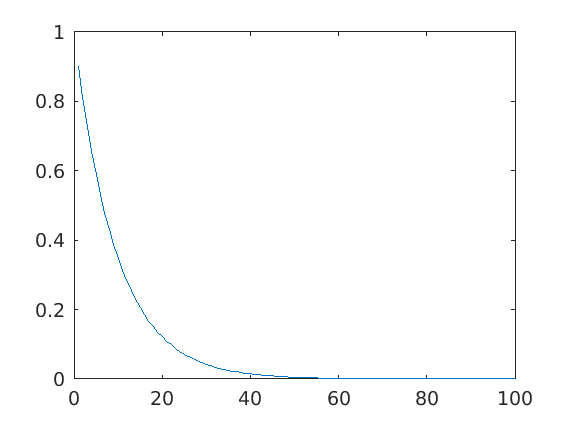

x = 1:100;
y = gamma.^x;
plot(y)

clf('reset')
steps = 0;
data_lengths = zeros(length(data),1);
for i_trial = 1:length(data)
    steps = steps + length(data{i_trial});
    data_lengths(i_trial) = length(data{i_trial});
end
steps = steps/length(data)

steps = 33.5600

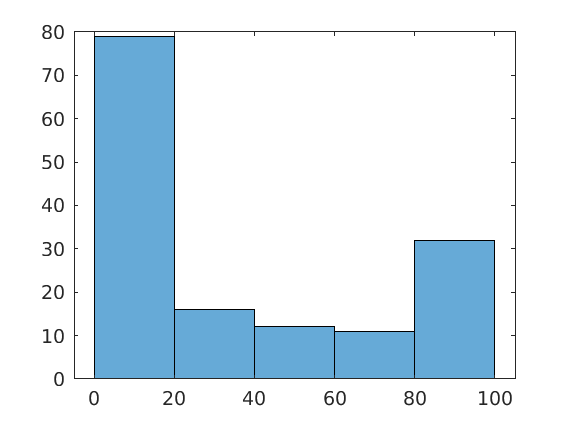

histogram(data_lengths); %, 'BinLimits',[0 1])

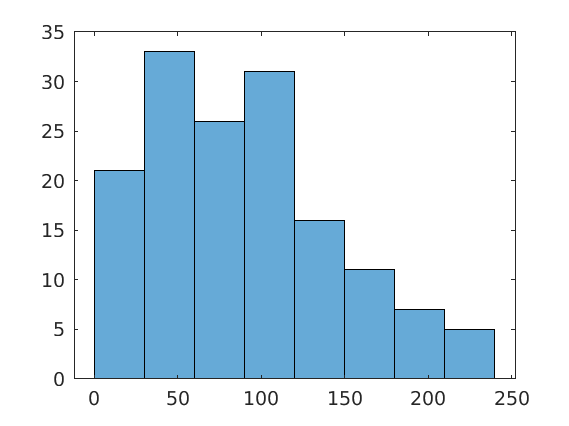

clf('reset')
max_forces = zeros(1,length(data));
for i = 1:length(data)
    max_forces(i) = max(data{i}(:,4));
end
histogram(max_forces);%, 'BinLimits',[0 1])

resistance_list = zeros(1,length(data));
for i = 1:length(data)
    resistance_list(i) = data{i}(1,2);
end

res_heavy_num = sum(resistance_list~=8);
res_light_num = sum(resistance_list==8);
max_forces_heavy = zeros(1,length(res_heavy_num));
max_forces_light = zeros(1,length(res_light_num));
rewarded_heavy = zeros(1,length(res_heavy_num));
rewarded_light = zeros(1,length(res_light_num));
h = 0;l = 0;
for i = 1:length(data)
    if resistance_list(i) ~= 8
        h = h + 1;
        max_forces_heavy(h) = max(data{i}(:,4));
        rewarded_heavy(h) = max(data{i}(:,5));
    else
        l = l + 1;
        max_forces_light(l) = max(data{i}(:,4));
        rewarded_light(l) = max(data{i}(:,5));
    end
end

% % add function to output resistance and max force of each trial
% Trials = 1:length(data);
% max_forces = zeros(1, length(data));
% for i = 1:length(data)
%     max_forces(i) = max(data{i}(:,4));
% end
% CSVFilename = [data_folder filesep Animal '_resistance_force_' Date '_' Key];
% Output = [transpose(Trials) transpose(resistance_list) transpose(max_forces)]
% csvwrite(CSVFilename,Output);

% % add function to output resistance, force (posterior) and observation
% % (pos(t)-pos(t-1))/force(t-1)
% 
% Output_tri = []; Output_res = []; Output_pos = []; Output_for = [];
% for i = 1:length(data)
%     Output_tri = [Output_tri; data{i}(:,1)];
%     Output_res = [Output_res; data{i}(:,2)];
%     Output_pos = [Output_pos; data{i}(:,3)];
%     Output_for = [Output_for; data{i}(:,4)];
% end
% % Trials = 1:length(data);
% % max_forces = zeros(1, length(data));
% % for i = 1:length(data)
% %     max_forces(i) = max(data{i}(:,4));
% % end
% CSVFilename = [data_folder filesep Animal '_resistance_force_pos_' Date '_' Key];
% Output2 = [Output_tri Output_res Output_pos Output_for]
% csvwrite(CSVFilename,Output2);

% To test behavior task works as expected, calcurate force and other
% behavior variables in each trials

FFthreshold     = 16;

maxForce        = zeros(size(data));
integralForce   = zeros(size(data));
trialDuration   = zeros(size(data));
rewarded        = zeros(size(data));
firstForce      = zeros(size(data));
trialResistance = zeros(size(data));
firstFlag       = zeros(size(data));
high90Flag      = zeros(size(data));

for i_animal = 1:size(data,1)
    if contains(Key{i_animal},'roving')
        Keynum = regexp(Key{i_animal}, '\d+','match');
        block_num = str2num(Keynum{1});
    end
    for j_trial = 1:totalTrial
        force_i_j = data{i_animal,j_trial}(:,4);
        maxForce(i_animal,j_trial) = max(force_i_j);
        integralForce(i_animal,j_trial) = sum(force_i_j(force_i_j > 0));
        trialDuration(i_animal,j_trial) = size(data{i_animal,j_trial},1)/fps;
        rewarded(i_animal,j_trial) = max(data{i_animal,j_trial}(:,5));
        for n_timestep = 1:length(force_i_j)
            if force_i_j(n_timestep) > FFthreshold
                firstForce(i_animal,j_trial) = force_i_j(n_timestep);
                break;
            end
        end
        trialResistance(i_animal,j_trial) = data{i_animal,j_trial}(1,2);
        if contains(Key,'roving')
            k = rem(j_trial,block_num);
            s = rem(j_trial,block_num*2);
            if k <= block_num/2
                firstFlag(i_animal,j_trial) = 1;
%             else
%                 firstHalf(i_animal,j_trial) = 0;
            end
            if s > block_num | s == 0
                high90Flag(i_animal,j_trial) = 1;
            end
        end
    end
end
behaviorVal = {maxForce,integralForce,trialDuration,rewarded,firstForce};

% separate trials by their resistance or position in a block and average
% them

allTrials = zeros(5,size(data,1));
highTrials = zeros(5,size(data,1));
lowTrials = zeros(5,size(data,1));
firstHalf = zeros(5,size(data,1));
secondHalf = zeros(5,size(data,1));
firstHalfhighTrials = zeros(5,size(data,1));
firstHalflowTrials = zeros(5,size(data,1));
secondHalfhighTrials = zeros(5,size(data,1));
secondHalflowTrials = zeros(5,size(data,1));

for j =1:5
    allTrials(j,:) = mean(behaviorVal{j},2);
    for i_animal = 1:size(data,1)
        highTrials(j,i_animal) = mean(behaviorVal{j}(i_animal,trialResistance(i_animal,:)~=8));
        lowTrials(j,i_animal) = mean(behaviorVal{j}(i_animal,trialResistance(i_animal,:)==8));
        firstHalf(j,i_animal) = mean(behaviorVal{j}(i_animal,firstFlag(i_animal,:)==1));
        secondHalf(j,i_animal) = mean(behaviorVal{j}(i_animal,firstFlag(i_animal,:)==0));
        firstHalfhighTrials(j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==1) & (trialResistance(i_animal,:)~=8)));
        firstHalflowTrials(j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==1) & (trialResistance(i_animal,:)==8)));
        secondHalfhighTrials(j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==0) & (trialResistance(i_animal,:)~=8)));
        secondHalflowTrials(j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==0) & (trialResistance(i_animal,:)==8)));
    end
end
behaviorVals = {allTrials,highTrials,lowTrials,firstHalf,secondHalf,firstHalfhighTrials,firstHalflowTrials,secondHalfhighTrials,secondHalflowTrials};

aveBehavioralVal = zeros(5,9);
ste = zeros(5,9);
for i = 1:9
    aveBehavioralVal(:,i) = mean(behaviorVals{i},2);
    ste(:,i) = std(behaviorVals{i},0,2);
end

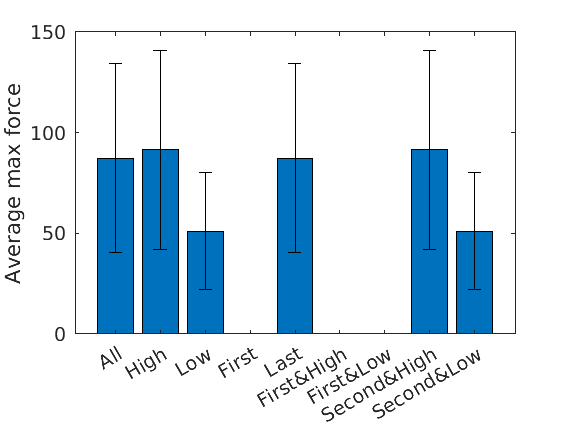

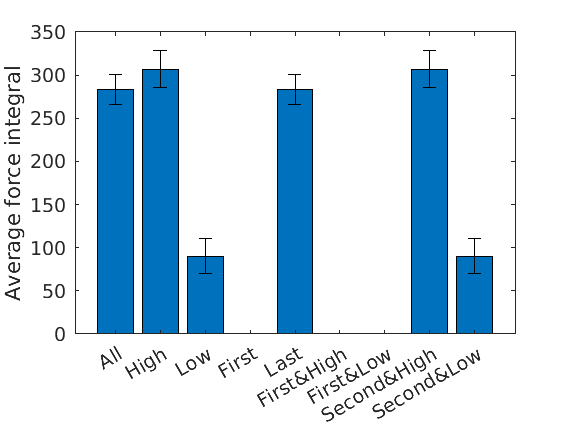

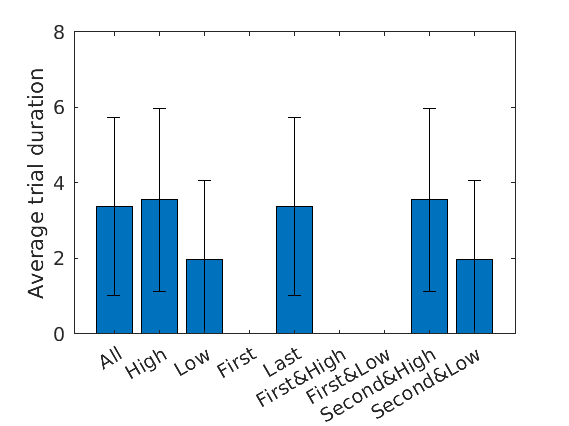

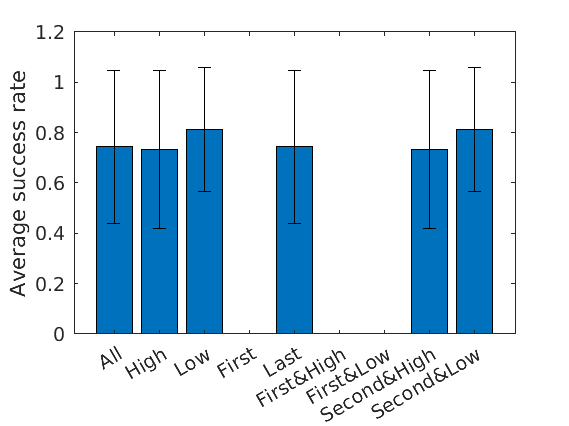

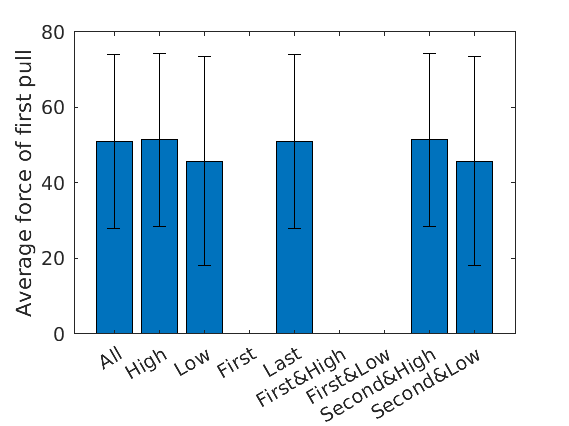

X = categorical({'All','High','Low','First','Last','First&High','First&Low','Second&High','Second&Low'});
X = reordercats(X,{'All','High','Low','First','Last','First&High','First&Low','Second&High','Second&Low'});
ylabels = {'Average max force','Average force integral','Average trial duration','Average success rate','Average force of first pull'};
title_keys = {'force_max','force_integral','trial_duration','success_rate','first_pull_force'};
for i = 1:5
    figure
    bar(X,aveBehavioralVal(i,:));
    hold on
    er = errorbar(X,aveBehavioralVal(i,:),ste(i,:),ste(i,:));
    er.Color = [0 0 0];
    er.LineStyle = 'none';
    ylabel(ylabels{i});
    if i == 1
        ylim([0,150]);
    elseif i == 3
        ylim([0,8]);
    end
    filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' strrep(strjoin(Key),' ','_') '_' title_keys{i} '.png'];
    saveas(gcf,filename);
end

behaviorVals{3}(3,:)

ans =     0.2063    4.9950    1.1667    3.2833    0.2778


% Statistical test
% Welch difference of mean
for i = 1:5
    high_trial = behaviorVals{2}(i,:);
    low_trial  = behaviorVals{3}(i,:);
    [h,p,ci,stats] = ttest2(high_trial,low_trial,'Vartype','unequal');
    fprintf('result of t test:\n')
    fprintf('t value = %.4f\n', stats.tstat)
    fprintf('degree of freedam = %.4f\n', stats.df)
    fprintf('p value = %.4f\n', p)
end

result of t test:


t value = 1.5788


degree of freedam = 6.4651


p value = 0.1619


result of t test:


t value = 16.3744


degree of freedam = 7.9649


p value = 0.0000


result of t test:


t value = 1.0986


degree of freedam = 7.8323


p value = 0.3046


result of t test:


t value = -0.4361


degree of freedam = 7.5585


p value = 0.6750


result of t test:


t value = 0.3544


degree of freedam = 7.7299


p value = 0.7325


CSVFilename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' strrep(strjoin(Key),' ','_') '_average_behaviors'];
% Output2 = [Output_tri Output_res Output_pos Output_for]
csvwrite(CSVFilename,aveBehavioralVal);

% separate trials by their resistance or position in a block and average
% them
if contains(Key,'roving')
    allTrials = zeros(3,5,size(data,1));
    highTrials = zeros(3,5,size(data,1));
    lowTrials = zeros(3,5,size(data,1));
    firstHalf = zeros(3,5,size(data,1));
    secondHalf = zeros(3,5,size(data,1));
    firstHalfhighTrials = zeros(3,5,size(data,1));
    firstHalflowTrials = zeros(3,5,size(data,1));
    secondHalfhighTrials = zeros(3,5,size(data,1));
    secondHalflowTrials = zeros(3,5,size(data,1));

    for j =1:5
        allTrials(1,j,:) = mean(behaviorVal{j},2);
        for i_animal = 1:size(data,1)
            highTrials(1,j,i_animal) = mean(behaviorVal{j}(i_animal,trialResistance(i_animal,:)~=8));
            lowTrials(1,j,i_animal) = mean(behaviorVal{j}(i_animal,trialResistance(i_animal,:)==8));
            firstHalf(1,j,i_animal) = mean(behaviorVal{j}(i_animal,firstFlag(i_animal,:)==1));
            secondHalf(1,j,i_animal) = mean(behaviorVal{j}(i_animal,firstFlag(i_animal,:)==0));
            firstHalfhighTrials(1,j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==1) & (trialResistance(i_animal,:)~=8)));
            firstHalflowTrials(1,j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==1) & (trialResistance(i_animal,:)==8)));
            secondHalfhighTrials(1,j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==0) & (trialResistance(i_animal,:)~=8)));
            secondHalflowTrials(1,j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==0) & (trialResistance(i_animal,:)==8)));
        end
    end
    for k = 2:3
        for j =1:5
            for i_animal = 1:size(data,1)
                allTrials(k,j,i_animal) = mean(behaviorVal{j}(i_animal,high90Flag(i_animal,:)==k-2));
                highTrials(k,j,i_animal) = mean(behaviorVal{j}(i_animal,(trialResistance(i_animal,:)~=8) & (high90Flag(i_animal,:)==k-2)));
                lowTrials(k,j,i_animal) = mean(behaviorVal{j}(i_animal,(trialResistance(i_animal,:)==8) & (high90Flag(i_animal,:)==k-2)));
                firstHalf(k,j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==1) & (high90Flag(i_animal,:)==k-2)));
                secondHalf(k,j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==0) & (high90Flag(i_animal,:)==k-2)));
                firstHalfhighTrials(k,j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==1) & (trialResistance(i_animal,:)~=8) & (high90Flag(i_animal,:)==k-2)));
                firstHalflowTrials(k,j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==1) & (trialResistance(i_animal,:)==8) & (high90Flag(i_animal,:)==k-2)));
                secondHalfhighTrials(k,j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==0) & (trialResistance(i_animal,:)~=8) & (high90Flag(i_animal,:)==k-2)));
                secondHalflowTrials(k,j,i_animal) = mean(behaviorVal{j}(i_animal,(firstFlag(i_animal,:)==0) & (trialResistance(i_animal,:)==8) & (high90Flag(i_animal,:)==k-2)));
            end
        end
    end
    behaviorVals = {allTrials,highTrials,lowTrials,firstHalf,secondHalf,firstHalfhighTrials,firstHalflowTrials,secondHalfhighTrials,secondHalflowTrials};

    aveBehavioralVal = zeros(3,5,9);
    ste = zeros(3,5,9);
    for i = 1:9
        aveBehavioralVal(:,:,i) = mean(behaviorVals{i},3);
        ste(:,:,i) = std(behaviorVals{i},0,3);
    end
    X = categorical({'All','High','Low','First','Last','First&High','First&Low','Second&High','Second&Low'});
    X = reordercats(X,{'All','High','Low','First','Last','First&High','First&Low','Second&High','Second&Low'});
    ylabels = {'Average max force','Average force integral','Average trial duration','Average success rate','Average force of first pull'};
    title_keys = {'force_max','force_integral','trial_duration','success_rate','first_pull_force'};
    session_type = {'all','low90','high90'};
    for k = 1:3
        for i = 1:5
            figure
            bar(X,reshape(aveBehavioralVal(k,i,:),[],1));
            hold on
            er = errorbar(X,reshape(aveBehavioralVal(k,i,:),[],1),reshape(ste(k,i,:),[],1),reshape(ste(k,i,:),[],1));
            er.Color = [0 0 0];
            er.LineStyle = 'none';
            ylabel(ylabels{i});
            title(session_type{k});
            filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' strrep(strjoin(Key),' ','_') '_' title_keys{i} '_' session_type{k} '.png'];
            saveas(gcf,filename);
        end
    end
    CSVFilename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' strrep(strjoin(Key),' ','_') '_average_behaviors'];
    % Output2 = [Output_tri Output_res Output_pos Output_for]
    csvwrite(CSVFilename,aveBehavioralVal);
end

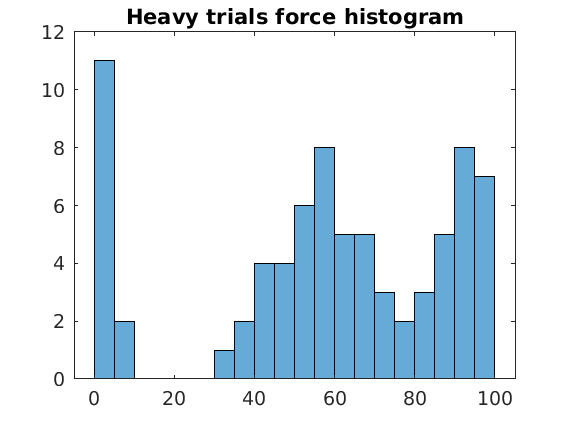

clf('reset')
edges = linspace(0, 100, 21);
histogram(max_forces_heavy, 'BinEdges',edges);%, 'BinLimits',[0 1])
title('Heavy trials force histogram');

mean(max_forces_heavy)

ans = 95.9429

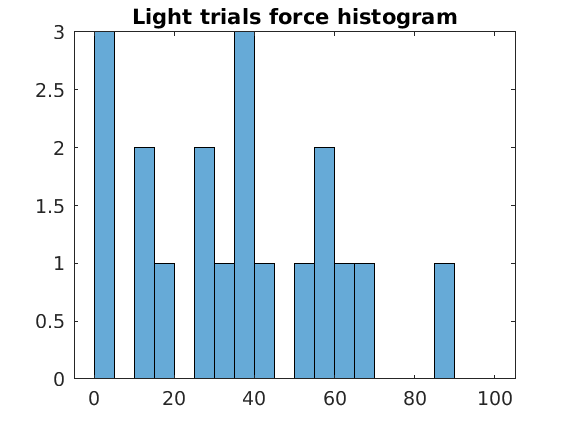

clf('reset')
edges = linspace(0, 100, 21);
histogram(max_forces_light, 'BinEdges',edges);%, 'BinLimits',[0 1])
title('Light trials force histogram');

mean(max_forces_light)

ans = 43.5698

success_rate_heavy = sum(rewarded_heavy)/length(rewarded_heavy)

success_rate_heavy = 0.7752

success_rate_light = sum(rewarded_light)/length(rewarded_light)

success_rate_light = 0.8571

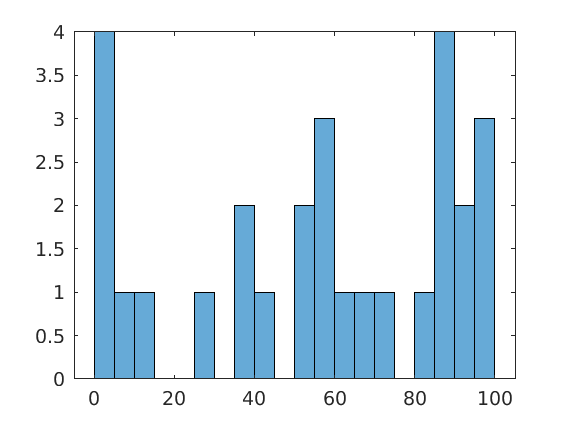

clf('reset')
max_forces = zeros(1,50);
for i = 1:50
    max_forces(i) = max(data{i}(:,4));
end
edges = linspace(0, 100, 21);
histogram(max_forces, 'BinEdges',edges);%, 'BinLimits',[0 1])

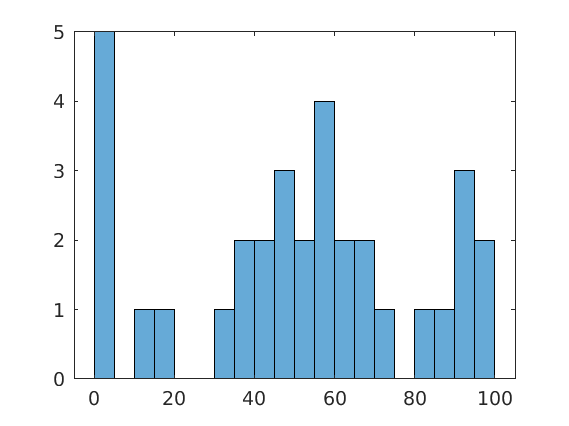

clf('reset')
max_forces = zeros(1,50);
for i = 1:50
    max_forces(i) = max(data{50+i}(:,4));
end
edges = linspace(0, 100, 21);
histogram(max_forces, 'BinEdges',edges);%, 'BinLimits',[0 1])

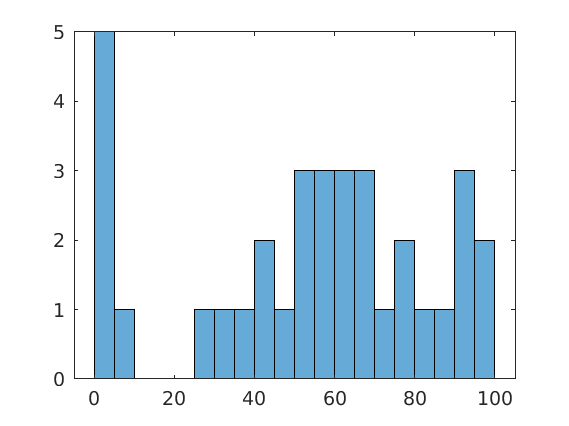

clf('reset')
max_forces = zeros(1,50);
for i = 1:50
    max_forces(i) = max(data{100+i}(:,4));
end
edges = linspace(0, 100, 21);
histogram(max_forces, 'BinEdges',edges);%, 'BinLimits',[0 1])